# load pmap with siibra

atlas = siibra.getAtlas('human');

    "Resolved query 'human' to: Multilevel Human Atlas"



julichbrain = atlas.getParcellation('Julich-Brain');

    "Resolved query 'Julich-Brain' to: Julich-Brain Cytoarchitectonic Maps 2.9"



mni_space = atlas.getSpace('MNI152 2009c nonl asym');

Fp1_region=julichbrain.decodeRegion('Area Fp1 (FPole) left');
Fp1_l_continous_region=Fp1_region.continuousMap(mni_space.Name);
Fp1_l_nifti=Fp1_l_continous_region.fetch();
Fp1_l_vol=Fp1_l_nifti.loadData();

## load template with siibra

mni_space = siibra.getSpace(atlas.Name,mni_space.Name);
mni_template = mni_space.loadTemplate;
vol_template=mni_template.normalizedData();

max(mni_template.loadData())

ans = 1×229×193 int16 array
ans(:,:,1) =

   -27537   -27176   -27018   -27070   -26408   -26341   -26054   -25679   -25321   -24759   -24256   -23887   -22990   -22581   -21106   -20210   -19420   -17456   -15168   -14078   -12494    -9051    -6702    -4722    -1606     1970     2605     5388     5999     6172     6546     7169     8169     7520     8594     9183    10062     9790    10381    10821    11812    13057    12895    14766    16814    17397    18467    18355    18107    19763    20734    21621    22045    21809    20544    21249    20299    19061    17402    15518    14645    14139    13577    11680    11499    11044    10781    11950    12343    11878    12403    12823    12236    11158    10639     8106     8809     8026     8639     8434     8157     9601    12537    15057    17141    16480    14827    12864     9738     7704     6705     6883     6205     6925     7041     7710     8333     8954     8285     9196     8760     8817     7763     8442     7991     8156    

## visualize pmap with template using volshow()

f = uifigure;
hVolume = volshow(vol_template, "Parent",f);
viewer = hVolume.Parent;


hVolume.RenderingStyle = "GradientOpacity";
viewer.BackgroundColor="white";
viewer.BackgroundGradient="off";
hVolume.Alphamap = linspace(0,0.2,256);
hVolume.OverlayAlphamap = 0.2;

hVolumeContinuous = volshow(vol_template, ...
    OverlayData=Fp1_l_vol, ...
    Parent=viewer, ...
    Alphamap=linspace(0,0.2,256), ...
    OverlayRenderingStyle="GradientOverlay", ...
    RenderingStyle="GradientOpacity");

hVolumeContinuous.OverlayAlphamap=linspace(0,0.5,256);
orthosliceViewer(vol_template, "Parent",viewer);

Error using images.stacks.browser.internal.SliceViewer/set.Parent
The Parent property must be a figure or uipanel.

Error in orthosliceViewer/parseInputs

Error in orthosliceViewer

fig = uifigure;
g = uigridlayout(fig, [2, 1]);
viewer = viewer3d(g);
viewer.Layout.Row = 2;
viewer.BackgroundColor="white";
viewer.BackgroundGradient="off";
hVolume = volshow(vol_template, "Parent",viewer);
hVolume.RenderingStyle = "GradientOpacity";
hVolume.Alphamap = linspace(0,0.2,256);
hVolume.OverlayAlphamap = 0.2;
hVolumeContinuous = volshow(vol_template, ...
    OverlayData=Fp1_l_vol, ...
    Parent=viewer, ...
    Alphamap=linspace(0,0.2,256), ...
    OverlayRenderingStyle="GradientOverlay", ...
    RenderingStyle="GradientOpacity");

hVolumeContinuous.OverlayAlphamap=linspace(0,0.5,256);

panel = uipanel(g);
panel.Layout.Row = 1;
orthoView = orthosliceViewer(vol_template, "Parent",panel);

vol_template

vol_template = 193×229×193 uint8 array
vol_template(:,:,1) =

     4     4     4     4     5     5     5     4     4     5     5     5     5     5     5     5     5     5     5     5     5     5     4     5     5     5     5     5     5     5     4     4     5     5     5     5     5     5     4     5     4     4     5     5     4     4     4     4     5     5     4     4     5     5     4     5     6     6     6     6     7     7     6     6     7     6     6     6     6     6     6     7     8     8     8    10    10    10    10    11    11    12    11    12    10     9     8     8     8     8     9     7     6     6     6     6     7     6     6     7     8     7     7     8     9     8     8     7     6     7     6     6     6     6     6     5     6     6     7     6     6     6     6     6     7     6     6     6     7     7     6     7     7     7     7     7     7     7     7     7     7     6     7     6     6     6     6     6     6     6     6     6     6     7     6     6  

Fp1_l_vol

Fp1_l_vol = 193×229×193 single array
Fp1_l_vol(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

volumeViewer(vol_template);

fig = uifigure;
g = uigridlayout(fig, [2, 2]);
viewer = viewer3d(g);
viewer.Layout.Row = 2;
viewer.Layout.Column = 2;
viewer.BackgroundColor="white";
viewer.BackgroundGradient="off";
hVolume = volshow(vol_template, "Parent",viewer);
hVolume.RenderingStyle = "GradientOpacity";
hVolume.Alphamap = linspace(0,0.2,256);
hVolume.OverlayAlphamap = 0.2;
hVolumeContinuous = volshow(vol_template, ...
    OverlayData=Fp1_l_vol, ...
    Parent=viewer, ...
    Alphamap=linspace(0,0.2,256), ...
    OverlayRenderingStyle="GradientOverlay", ...
    RenderingStyle="GradientOpacity");

hVolumeContinuous.OverlayAlphamap=linspace(0,0.5,256);

cmap = colormap("jet");
cmap(1, :) = [0, 0, 0];
color_indices = cast(Fp1_l_vol * 254 + 1, "uint8");
probability_color_volume = reshape(cmap(color_indices, :), [size(Fp1_l_vol), 3]);

cmap = colormap("gray");
color_indices = vol_template;
template_color_volume = reshape(cmap(color_indices, :), [size(vol_template), 3]);

mixed_volume = template_color_volume;
mixed_volume(Fp1_l_vol>0) = probability_color_volume(Fp1_l_vol>0);

panel1 = uipanel(g);
panel1.Layout.Row = 1;
panel1.Layout.Column = 1;
sliceViewer(mixed_volume, "Parent",panel1, "SliceDirection","X");

panel2 = uipanel(g);
panel2.Layout.Row = 2;
panel2.Layout.Column = 1;
sliceViewer(mixed_volume, "Parent",panel2, "SliceDirection","Y");

panel3 = uipanel(g);
panel3.Layout.Row = 1;
panel3.Layout.Column = 2;
sliceViewer(mixed_volume, "Parent",panel3, "SliceDirection","Z");


cmap = colormap("jet");
cmap(1, :) = [0, 0, 0];
color_indices = cast(Fp1_l_vol * 254 + 1, "uint8");
probability_color_volume = reshape(cmap(color_indices, :), [size(Fp1_l_vol), 3]);

cmap = colormap("gray");
color_indices = vol_template;
template_color_volume = reshape(cmap(color_indices, :), [size(vol_template), 3]);

mixed_volume = template_color_volume;
mixed_volume(Fp1_l_vol>0) = probability_color_volume(Fp1_l_vol>0);
sliceViewer(mixed_volume, "SliceDirection","X") % "Colormap",cmap);

ans =   sliceViewer with properties:

             SliceDirection: 'X'
                SliceNumber: 97
                     Parent: [1×1 Panel]
                   Colormap: [256×3 double]
               DisplayRange: [0 1]
               ScaleFactors: [1 1 1]
    DisplayRangeInteraction: 'off'


size(Fp1_l_vol>0)

ans =    193   229   193


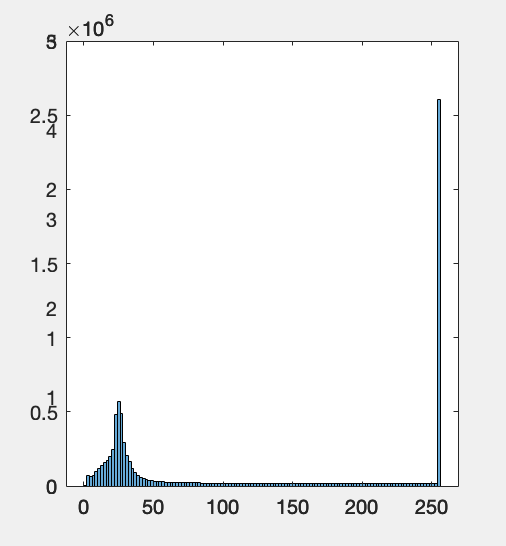

%histogram(vol_template(:))

ans =          0         0    0.5156
         0         0    0.5156
         0         0    0.5156
         0         0    0.5156
         0         0    0.5156
         0         0    0.5156
         0         0    0.5156
         0         0    0.5156
         0         0    0.5156
         0         0    0.5156


## load mpm with siibra

mpm=julichbrain.parcellationMap(mni_space.Name);
mpm_vol=mpm.fetch.loadData();

Error using matlab.internal.webservices.HTTPConnector/copyContentToFile
The server returned the status 404 with message "Not Found" in response to the request to URL
https://siibra-api-stable.apps.hbp.eu/v1_0/map/labelled_map.nii.gz?parcellation_id=minds/core/parcellationatlas/v1.0.0/94c1125b-b87e-45e4-901c-00daee7f2579-290&space_id=minds/core/referencespace/v1.0.0/dafcffc5-4826-4bf1-8ff6-46b8a31ff8e2.

Error in websave (line 107)
copyContentToFile(connection, filename);

E


% mpm_vol   => The loaded mpm (labeld map) has different dimensions compared to the template?
% mpm_vol   => seems to be only one mask of one area  (max(mpm_vol,[],'all')=> 1)

## read mpm version 3.0.1 with spm

%mpm_h=spm_vol('JulichBrainAtlas_3.0_areas_MPM_b_N10_nlin2ICBM152asym2009c.nii.gz');

%The MPM from the JBA 3.0 with both hemispheres cannot be displayed
% this way, because only max. 256 labels are allowed.

mpm_h=spm_vol('JulichBrainAtlas_3.0_areas_MPM_l_N10_nlin2ICBM152asym2009c.nii.gz');
mpm_spm=spm_read_vols(mpm_h);


volumeViewer(vol_template,mpm_spm)
% The area names should be passed as label names.
% Ideally, the RGB values of the areas should
% also be passed so that a similar look
% to the siibra explorer is created.